# Find Content in Presentation

Import the PPT package so that you do not have to use long, fully qualified names for the PPT API classes.

import mlreportgen.ppt.*

Create a presentation. Add two slides that have titles.

ppt = Presentation('myPresentation.pptx');
open(ppt);
add(ppt,'Title Slide');
add(ppt,'Title and Content');

Find presentation objects whose `Name` property is `Title`.

contents = find(ppt,'Title')

The `find` method returns a 1-by-2 array of `mlreportgen.ppt.TextBoxPlaceholder` objects. The first object is for the title in the first slide and the second object is for the title in the second slide.

Replace the title in the first slide with `My Presentation Title`. 

p = Paragraph('My Presentation Title');
replace(contents(1),p);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the generated presentation:

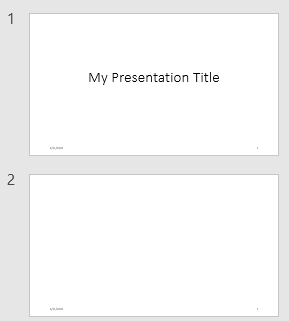

*Copyright 2020 The MathWorks, Inc.*